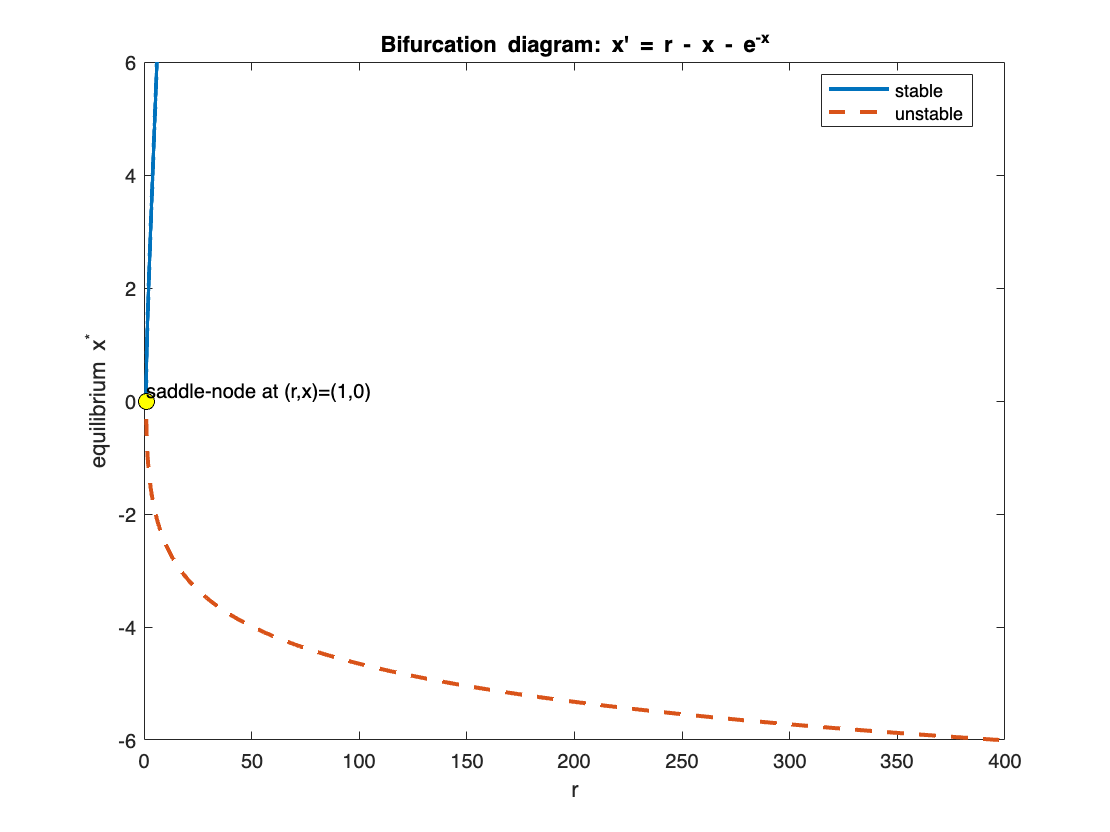

%% ================================================================
%  3) Saddle-node example: x' = r - x - exp(-x)
%     Analyze equilibria via r = x + exp(-x)
% ================================================================

% We can parametrize equilibria by x and compute r(x).
x = linspace(-6,6,4001);
r_of_x = x + exp(-x);                 % equilibrium condition r = x + e^{-x}
% Stability from f_x = d/dx (r - x - e^{-x}) = -1 + e^{-x}
fx = -1 + exp(-x);
isStable = fx < 0;                    % stable if derivative negative

figure('Name','Bifurcation: r - x - exp(-x)','Color','w'); hold on; box on;
% Plot stable/unstable parts
plot(r_of_x(isStable), x(isStable), 'LineWidth',2);
plot(r_of_x(~isStable), x(~isStable), '--', 'LineWidth',2);

% Highlight saddle-node point: minimum of r(x) occurs at x=0 => r=1
plot(1,0,'ko','MarkerFaceColor','y','MarkerSize',8);
text(1.03,0.2,'saddle-node at (r,x)=(1,0)','FontSize',10);

xlabel('r'); ylabel('equilibrium x^*');
title('Bifurcation diagram: x'' = r - x - e^{-x}');
legend('stable','unstable','Location','best');

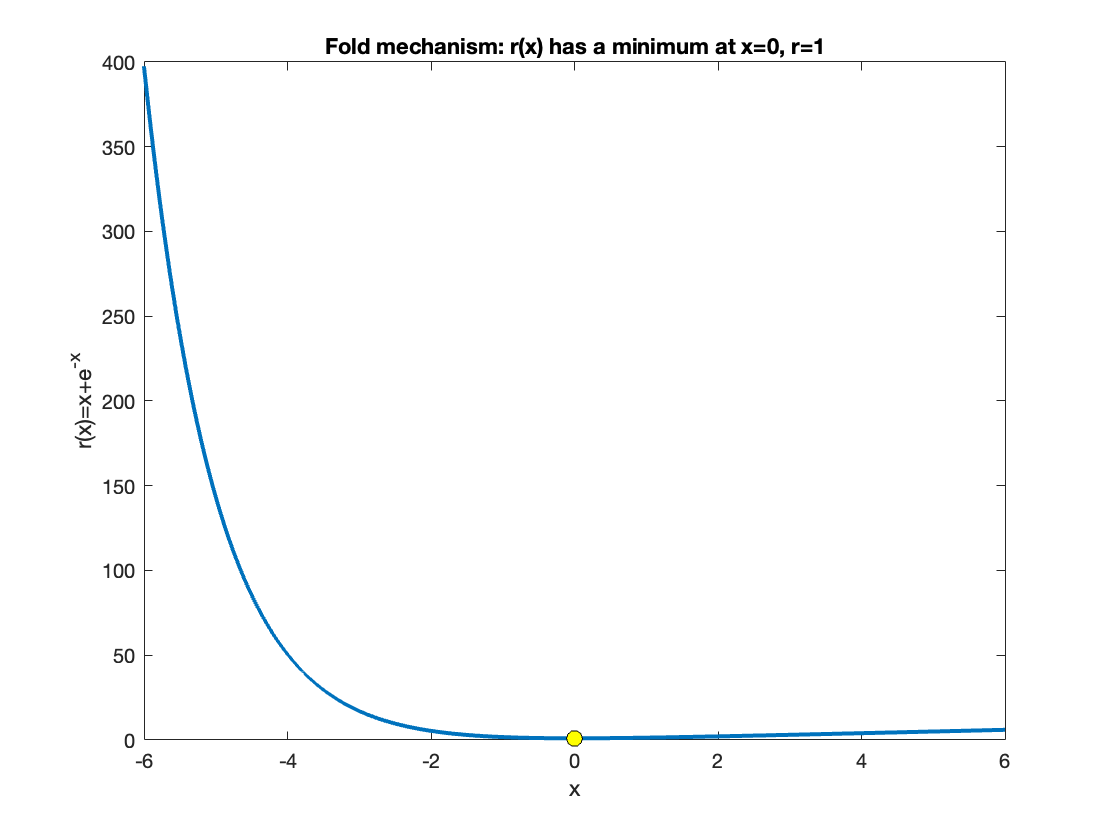


% Optional: show r(x) curve to emphasize "fold"
figure('Name','r(x) curve for r - x - exp(-x)','Color','w'); hold on; box on;
plot(x, r_of_x,'LineWidth',2);
plot(0,1,'ko','MarkerFaceColor','y','MarkerSize',8);
xlabel('x'); ylabel('r(x)=x+e^{-x}');
title('Fold mechanism: r(x) has a minimum at x=0, r=1');